## Question 5 - Data-Driven Modelling

**For all parts of the question, provide your discussion in bullet points.**

**(a) Consider the following time-series model for the count of vehicles, Y (t), on a road in Bristol. One unit of time is 12 hours, so at t = 0, the total count for 12 hours (7am-7pm) is given, and at t = 1 the count for the following 12 hours is given. Counts are given in 1000s of vehicles, so Y (t) = 5 means 5, 000 vehicles were counted. **

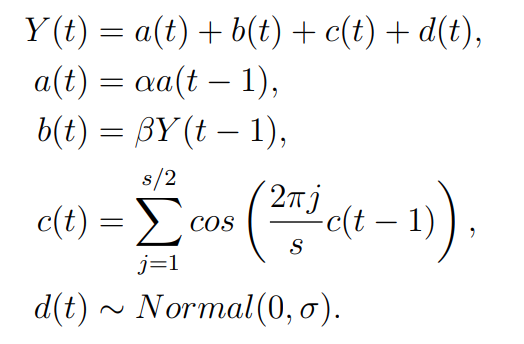

**The parameters of the model have been estimated to take the following values, based on observational data: α = 0.99, β = 0.5, s = 4, and σ = 0.1**

% Parameters estimted based on observational data
alpha = 0.99;
beta = 0.5;
s = 4;
sigma = 0.1;

**(i) Describe the dynamics produced by this model for the initial condition Y (0) = 0, a(0) = 0.75, c(0) = 0.5. Include a sketch/plot in your answer.**

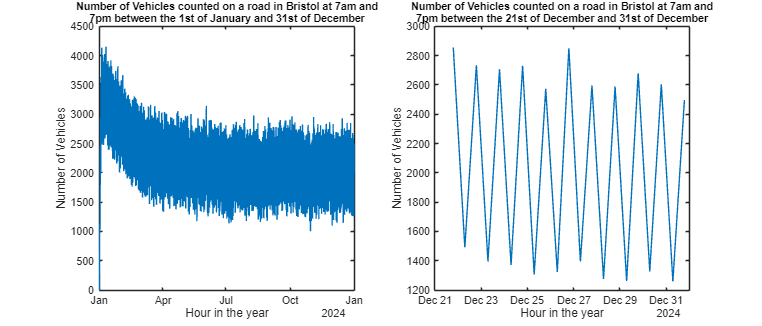

% The number of uses of the equation necessary to produce a full year's
% worth of data - inclusive
CyclesInYear = 365*2+2;

% Setting up the necessary arrays for time series model for count of
% vehicles
Y = zeros(CyclesInYear,1);
a = zeros(CyclesInYear,1);
b = zeros(CyclesInYear,1);
c = zeros(CyclesInYear,1);
Norm = makedist('Normal','mu',0,'sigma',sigma);
d = zeros(CyclesInYear,1);

% Setting the inital conditions
Y(1) = 0;
a(1) = 0.75;
c(1) = 0.5;
d(1) = random(Norm);
b(1) = Y(1) - a(1) - c(1) - d(1);

% Calculatio of time series model predictions of vehicle count
for t=2:CyclesInYear
    % Equations used to calcaulte time series model
    a(t) = alpha*a(t-1);
    b(t) = beta*Y(t-1);

    for i=1:s/2 
       c(t) = c(t) + cos((2*pi*i/s)*c(t-1));
    end
    d(t) = random(Norm);
    
    % Calculation of time series model prediction
    Y(t) = a(t) + b(t) + c(t) + d(t);
end

StartDate = datetime(2024,1,1, 7, 0, 0);
EndDate = datetime(2024,12,31, 19, 0, 0);
X = StartDate:hours(12):EndDate;

% Setting up figure
figure;

% Plotting all values obtained by the time-series model
ax1 = subplot(1,2,1);
plot(X,Y*1000)
xlabel("Hour in the year")
ylabel("Number of Vehicles")
title(sprintf("Number of Vehicles counted on a road in Bristol at 7am and" + ...
    "\n7pm between the 1st of January and 31st of December"),"fontsize",10)

% Plotting the final 20 values obtained by the time-series model
ax2 = subplot(1,2,2);
plot(X(CyclesInYear-20:CyclesInYear),Y(CyclesInYear-20:CyclesInYear)*1000)
xlabel("Hour in the year")
ylabel("Number of Vehicles")
title(sprintf("Number of Vehicles counted on a road in Bristol at 7am and" + ...
    "\n7pm between the 21st of December and 31st of December"),"fontsize",10)

set(gcf,'units','inches','position',[0,0,14,6])

The dynamics in this model are as follows:

- Average around 2100 vehicles in a 24 hour period, with typical deivation of around 500. This gives an approximate traffic flow of 175 vehicles per hour over a day, with approximately 233 vehicles per hour during the day (7am to 7pm) and 116 at night (7pm to 7am). This is approximately one vehicle every 15 seconds in the day and 31 seconds at night.

- a is a steadily decreasing positive value that follows an approximately exponential curve while b is much more fluctuating with b staying positive (apart from the inital value) between 0.65 and 1.45 for night and day respectively. c has the values of 0 and 2 after the initial spike, occupying the value of 2 in the day and 0 at night, suggesting the approximate 2000 vehicle difference between night and day. d is a random noise term that doesn't follow a trend.

- The model settles after an initial spike caused by the initial condition of Y(0) = 0 but there are still some large peaks and troughs at seemingly random intervals

- There is no distinction between weekdays and weekends or seasons (i.e. decreased counts during school/university holidays) and it assumes there is no traffic lights, queues or road works.

**(ii) Discuss the usefulness of this model with the given parameter estimates for forecasting and explaining the dynamics of vehicle traffic counts on the road in Bristol, clearly justifying the arguments you make.**

What are the positives?

- The model is useful for predicting traffic flow over a long time period i.e. a month or a year. It is most likely quite accurate for these time frames as any outliers are likely to be average out over this time frame.This is useful when looking at a flow rate over a whole year or such to see what traffic is like on the macro-scale.

- After the inital period, the model settles to approximate steady values over 12 hours, highlighting the much lower traffic count at night compared to day. This is also useful as it means a day-by-day situation of the model is possible to obtain and is accurate to a degree.

What are the drawbacks?

- This model uses very low "sampling" i.e. one sample every 12 hours so, for example, if a traffic model of this part of the network was desired to be on an hour-by-hour or minute-by-minute scale it is going to be inaccruate. This is simply because interpolating between the peak and trough over the 24-hour period is too crude a method to use. Fitting these two points to a curve could be a method around this but is heavily dependent on the curve selected.

- As previously stated the model doesn't take into account seasonal variations. This is significant as Bristol, a student and young person heavy city, is often busiest when term-time is around i.e. from the months September through to May. This isn't reflected in the model at all and just assumes that traffic flow remains the same all year round. There is a similar impact for if a road is placed near a school.

- There are also more variations to do with type of use as for example if the road is right next to a school, the traffic flow is likely to be heavily dependent on school timetable and demographic of students/parents too. In effect, if the school is located close to the road and is private or placed in a wealthy area the traffic flow is likely to be higher. 

- The model also doesn't take into account traffic lights, queues or road works that could imapct traffic flow on this road. This could once again have significant impact on hour-by-hour and minute-by-minute approximations from the data but is unlikely to affect the model at a larger scale. This once again limits the model to longer rather than shorter time frames to sample out of.

**(b) This questions extends the worked direct demand modelling example on pedestrian traffic data from Melbourne covered in the lab sheet for data-driven modelling.**

**Guideline to allocation of marks for part (b):**

** • Simple answers build on the code and data provided in the lab sheet. **

**• Good answers consider additional data. **

**• Excellent answers start from scratch, obtaining all data from primary sources. **

**• Use a similar spatial and temporal coverage as shown in the lab sheet example, there are no extra marks for considering larger areas or longer time-frames. **

**(i) Develop and implement in code (Python or Matlab) a regression-based direct demand model for central Melbourne pedestrian traffic to forecast traffic on all links of part of the network 2 hours in advance. Provide a clear explanation and rationale for the model you choose, and for any additional data you obtain. **

For this question, I obtained two sets of additional data: data from the Melbourne traffic data website for the sensors for June, July and August from 2019 to 2024 and a set of COVID coefficients i.e. how much in Melbourne the pedestrian traffic decreased in Melbourne during those times obtained from these two sources (90% reduction in 2020 [ATRF2021_Resubmission_40-1.pdf](https://australasiantransportresearchforum.org.au/wp-content/uploads/2022/05/ATRF2021_Resubmission_40-1.pdf) and 30% in 2022 [Has CBD pedestrian activity in Melbourne recovered since Covid-19? - RMIT University](https://www.rmit.edu.au/news/acumen/pedestrian_counts), a mean of this was taken for 2021 i.e. 60% reduction). The rationale behind this was to give the model more data to train on and see what the impact of this extra data and appropixamtion of COVID impact had compared to the lab sheet results obtained with a smaller sample size.

Following on from this, I chose the Seasonal ARIMA model (SARIMA) as the first part of my regression-based direct demand model. This model was chosen as it was deemed to be able to handle incomplete datasets appropriately and produce more accurate results than the ARIMA model due to the seasonality being set to a 24 hour period. The LSTM was inappropriate here as it was researched and appeared to not handle missing data points well. 

The second part of my regression based direct demand model was a gravity model where the impact of each sensor on the link is directly proportional to 1/(distance between sensor and link)^2. This is thought to be a relatively good estimate for the impact of links on other links due to the wide use of the gravity model in other parts of transport and mobility modelling, especially demand modelling (and this unit!). This was how the traffic flow on each link was predicted for the network 2 hours in advance.

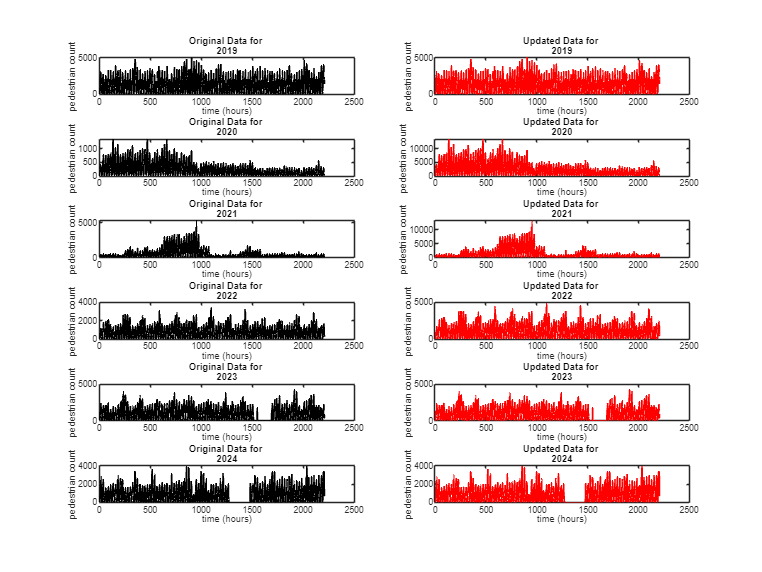

% read in data from pedestrian counters
% hourly counts for 13 counters for 52 days in June and July 2019.

opts = delimitedTextImportOptions("NumVariables", 102);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

SensorNames = ["MelbourneCentral", "LonsdaleSt-ElizabethSt(North)",...
"ElizabethSt-LonsdaleSt(South)","MelbourneCentral-ElizabethSt(East)","StateLibrary",...
"LonsdaleSt(South)","Chinatown-SwanstonSt(North)","Chinatown-LtBourkeSt(South)",...
"BourkeSt-RussellSt(West)","BourkeStreetMall(North)","BourkeStreetMall(South)",...
"LittleCollinsSt-SwanstonSt(East)","TownHall(West)"];

% Specify column names and types
opts.VariableNames = ["Date", "Hour", SensorNames];
opts.SelectedVariableNames = ["Date", "Hour", SensorNames];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double", "double",...
    "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Date", "InputFormat", "dd/MM/yyyy", "DatetimeFormat", "preserveinput");
opts.VariableNamingRule = 'preserve';  % This will preserve the original column names

StartYear = 2019;
EndYear = 2024;

AllData = cell(length(StartYear:EndYear),3);
dates = [];
OriginalData = [];
UpdatedData = [];
%dates = zeros(length(StartYear:EndYear)*(720+744+744));

for i=StartYear:EndYear
    JunePath = strcat("..\Q5 - Data Driven Modelling\Data\","June_",string(i),".csv"); 
    JulyPath =  strcat("..\Q5 - Data Driven Modelling\Data\","July_",string(i),".csv");
    AugustPath =  strcat("..\Q5 - Data Driven Modelling\Data\","August_",string(i),".csv");

    JuneTab = readtable(JunePath, opts);
    JulyTab = readtable(JulyPath, opts);
    AugustTab = readtable(AugustPath, opts);

    AllData{(i-(StartYear-1)),1} = JuneTab(:,:);
    AllData{(i-(StartYear-1)),2} = JulyTab(:,:);
    AllData{(i-(StartYear-1)),3} = AugustTab(:,:);

    dates = [dates; table2array(JuneTab(:,1)); table2array(JulyTab(:,1)); table2array(AugustTab(:,1))];
    OriginalData = [OriginalData; table2array(JuneTab(:,3:15)); table2array(JulyTab(:,3:15)); table2array(AugustTab(:,3:15))];
    % 2020 - 90% reduction value  i.e. 10% of 2019 figures
    if i == 2020
        UpdatedData = [UpdatedData; table2array(JuneTab(:,3:15))*(100/10); table2array(JulyTab(:,3:15))*(100/10); table2array(AugustTab(:,3:15))*(100/10)];
        %2021 - middle between the two values about and below: 60%
        %reduction i.e. 40% of 2019 figures
    elseif i == 2021
        UpdatedData = [UpdatedData; table2array(JuneTab(:,3:15))*(100/40); table2array(JulyTab(:,3:15))*(100/40); table2array(AugustTab(:,3:15))*(100/40)];
        %2022 - 70% of 2019 figures i.e. 30% reduction 
    elseif i == 2022
        UpdatedData = [UpdatedData; table2array(JuneTab(:,3:15))*(100/70); table2array(JulyTab(:,3:15))*(100/70); table2array(AugustTab(:,3:15))*(100/70)];
    else
        UpdatedData = [UpdatedData; table2array(JuneTab(:,3:15)); table2array(JulyTab(:,3:15)); table2array(AugustTab(:,3:15))];
    end
end

clear opts
years = StartYear:EndYear;
index = 1;

figure;
for i = 1:length(StartYear:EndYear)
    subplot(length(StartYear:EndYear),2,2*i-1)
    plot(OriginalData(index:index+(720+744+743),5), 'k', 'LineWidth', 1.5);
    title(["Original Data for " years(i)'])
    xlabel('time (hours)');
    ylabel('pedestrian count');

    subplot(length(StartYear:EndYear),2,2*i)
    plot(UpdatedData(index:index+(720+744+743),5),'r', 'LineWidth', 1.5);
    title(["Updated Data for " years(i)'])
    xlabel('time (hours)');
    ylabel('pedestrian count');
    
    index = index + (720+744+744);

end

set(gcf,'units','inches','position',[0,0,16,12])

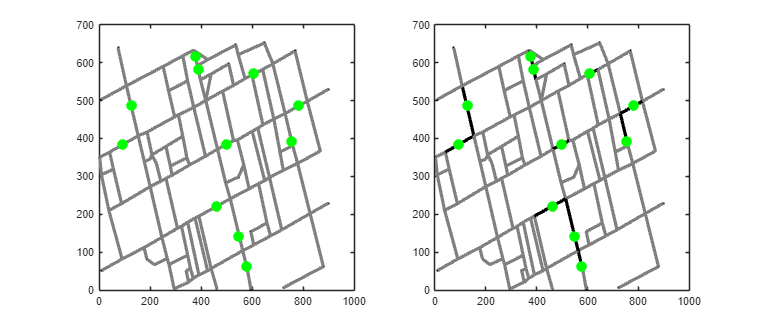

UpdatedData = UpdatedData';

% read in xy cooordinates for line segments that define the road network
% for the central part of Melbourne investigated here
% (in arbitrary units that could be rescaled to metres)
xs = load('lines_xs.txt');
ys = load('lines_ys.txt');
ys = 655 - ys; % this resetting of y-values is just for plotting purposes
%... usually, you would have to obtain these line segments from mapping
%tools, e.g. Open Street Maps.

% read in sensor xy coordinates (in arbitrary units that could be rescaled to metres)
sensx = load('sensors_xs.txt');
sensy = load('sensors_ys.txt');
%sensy = 655 - sensy; % this resetting of y-values is just for plotting purposes

% Convert street segments to network

% Initialize adjacency matrix
n = length(xs) / 2;
A = zeros(n, n);

% Calculate adjacency matrix
% the specifics of this are down to the format of the files
% edges indicate that two road segments are directly connected.
% the weight is 1/2 of both road segment lengths added together.
for i = 1:n
    for j = i:n
        if i ~= j
            % here we check if the two road segments share a start/end
            % coordinate
            xdiff = abs([xs(2*i-1)-xs(2*j-1), xs(2*i-1)-xs(2*j), xs(2*i)-xs(2*j-1), xs(2*i)-xs(2*j)]);
            ydiff = abs([ys(2*i-1)-ys(2*j-1), ys(2*i-1)-ys(2*j), ys(2*i)-ys(2*j-1), ys(2*i)-ys(2*j)]);
            diff = xdiff + ydiff;
            if any(diff == 0)
                % here compute the distance, as described above
                % this calculation could be changed, e.g. to include
                % factors that influence the distance perceived by
                % pedestrians, e.g. the pleasantness of links...
                A(i, j) = (sqrt((xs(2*i-1) - xs(2*i))^2 + (ys(2*i-1) - ys(2*i))^2)/2 + sqrt((xs(2*j-1) - xs(2*j))^2 + (ys(2*j-1) - ys(2*j))^2)/2);
                A(j, i) = A(i, j);
            end
        end
    end
end

%% Find road segments containing sensors
n = length(xs) / 2;
midsx = (xs(1:2:end) + xs(2:2:end)) / 2;
midsy = (ys(1:2:end) + ys(2:2:end)) / 2;
nsens = length(sensx);
idsens = NaN(nsens, 1);

for i = 1:nsens
    dds = sqrt((midsx - sensx(i)).^2 + (midsy - sensy(i)).^2);
    if i == 9
        [~, oo] = sort(dds);
        idsens(i) = oo(2);
    else
        [~, idsens(i)] = min(dds);
    end
    %disp(idsens(i));
end

% Plot the x and y coordinates
figure;
subplot(1,2,1);
plot(xs, ys, 'k.');  % Plot as points (black dots)
hold on;

% Get number of line segments
n = length(xs) / 2;

% Links x1 x2 y1 y2
links = zeros(length(xs),4);
% Midpoints of links
linksMidpoints = zeros(length(xs),2);

% Loop through and plot each line segment
for i = 1:n
    % Color of the segment (grey)
    coll = [0.5, 0.5, 0.5]; % RGB for grey

    % Plot line segment with specified color and width
    line([xs(2*i-1), xs(2*i)], [ys(2*i-1), ys(2*i)], 'Color', coll, 'LineWidth', 3);
    % Getting coordinates of links
    links(i,:) = [xs(2*i-1), xs(2*i), ys(2*i-1), ys(2*i)];
    linksMidpoints = [(xs(2*i-1)+xs(2*i))/2, (ys(2*i-1)+ys(2*i))/2];
end

% Show sensor locations as green points
scatter(sensx, sensy, 100, 'g', 'filled'); % Size 100, color green, filled circles

hold off;


%% Plot the segments and sensor locations
% segments associated with sensors are highlighted in the plot
subplot(1,2,2);
plot(xs, ys, 'k.');
hold on;
for i = 1:n
    if ismember(i, idsens)
        line([xs(2*i-1), xs(2*i)], [ys(2*i-1), ys(2*i)], 'Color', 'k', 'LineWidth', 3);
    else
        line([xs(2*i-1), xs(2*i)], [ys(2*i-1), ys(2*i)], 'Color', [0.5, 0.5, 0.5], 'LineWidth', 3);
    end
end

scatter(sensx, sensy, 100, 'g', 'filled');
hold off;
set(gcf,'units','inches','position',[0,0,14,6])

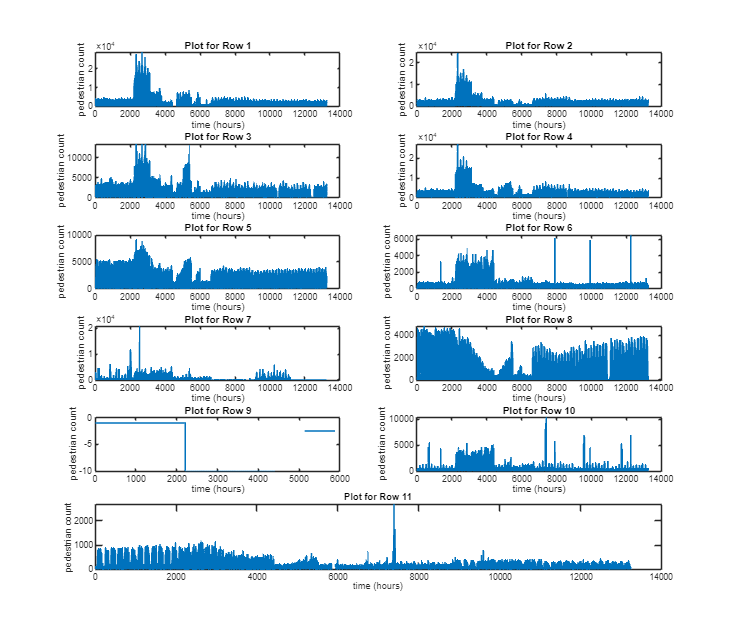



%% Merge sensors in the same location
signal = NaN(length(unique(idsens)), size(UpdatedData, 2));
cc = 1;
c = 1;
while c <= length(unique(idsens))
    if sum(idsens == idsens(cc)) > 1
        signal(c, :) = UpdatedData(cc, :) + UpdatedData(cc+1, :);
        % add counts of sensors on the same street segments, as these are
        % typically on opposite sides of the road.
        cc = cc + 2;
        c = c + 1;
    else
        signal(c, :) = UpdatedData(cc, :) * 2;
        % double the counts of sensors that do not share the street segment
        % with another sensor, as these usually cover only one side of the
        % roaddatetime();datetime();datetime();datetime();datetime();datetime();datetime();datetime();uniqueindexesuniqueindexesuniqueindexesuniqueindexesuniqueindexesuniqueindexesuniqueindexesuniqueindexes
        cc = cc + 1;
        c = c + 1;
    end
end
[sensnodes,uniqueindexes] = unique(idsens); % we're left with 11 sensors out of the original 13.
UnqiueSensorNames = SensorNames(uniqueindexes);
UniqueSensx = sensx(uniqueindexes);
UniqueSensy = sensy(uniqueindexes);

UpdatedData = UpdatedData(uniqueindexes,:);

%% Compute shortest paths between nodes and sensors
net = graph(A);
alldists2 = distances(net, sensnodes);

% select the time series from the data that we will use throughout this section:
figure;

for i = 1:length(UnqiueSensorNames)-1
    subplot(round(length(UnqiueSensorNames)/2),2,i); % Create a 4x1 grid of subplots and select the i-th one
    plot(UpdatedData(i, :), 'LineWidth', 1.5); % Plot the i-th row of data
    title(['Plot for Row ' num2str(i)]); % Title for each subplot
    xlabel('time (hours)');
    ylabel('pedestrian count');
end

subplot(round(length(UnqiueSensorNames)/2),2,11:12); % Create a 4x1 grid of subplots and select the i-th one
plot(UpdatedData(11, :), 'LineWidth', 1.5); % Plot the i-th row of data
title(['Plot for Row ' num2str(11)]); % Title for each subplot
xlabel('time (hours)');
ylabel('pedestrian count');
set(gcf,'units','inches','position',[0,0,16,14])

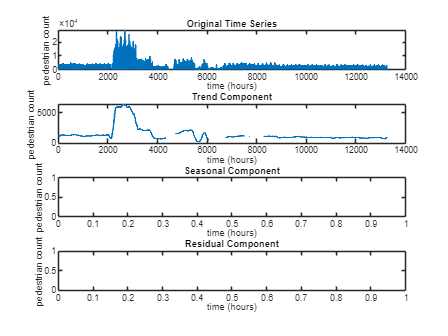



% select the time series from the data that we will use throughout this section:
timeseries = UpdatedData(1,:);
n = length(timeseries);

% Plot the original time series
figure;
subplot(4,1,1);
plot(timeseries, 'LineWidth', 1.5);
title('Original Time Series');
xlabel('time (hours)');
ylabel('pedestrian count');

%% TREND COMPONENT
% Using a moving average filter to estimate the trend component
window_size = 24*7; % Adjust the window size for the moving average (e.g., weekly)
trend_component = movmean(timeseries, window_size);

% Subtract the trend component from the original series to get the detrended data
detrended = timeseries - trend_component;

% Plot the trend component
subplot(4,1,2);
plot(trend_component, 'LineWidth', 1.5);
title('Trend Component');
xlabel('time (hours)');
ylabel('pedestrian count');

%% SEASONAL COMPONENT
% Assuming the seasonality repeats every 'window_size2' (e.g., daily)
window_size2 = 24;
seasonal_component = detrended(1:window_size2); % First complete seasonal cycle
% compute average over all observed seasonal cycles:
for i = 2:ceil(n/window_size2)
    seasonal_component = seasonal_component + detrended(((i-1)*window_size2+1):(i*window_size2));
end


seasonal_component = seasonal_component/ceil(n/window_size2);
seasonal_component = repmat(seasonal_component, 1, ceil(n/window_size2));
%seasonal_component = seasonal_component(1:n); % Trim to match time series length
% Plot the seasonal component
subplot(4,1,3);
plot(seasonal_component, 'LineWidth', 1.5);
title('Seasonal Component');
xlabel('time (hours)');
ylabel('pedestrian count');

%% RESIDUAL (RANDOM) COMPONENT
residual_component = timeseries - trend_component - seasonal_component;

% Plot the residual component
subplot(4,1,4);
plot(residual_component, 'LineWidth', 1.5);
title('Residual Component');
xlabel('time (hours)');
ylabel('pedestrian count');


% As we have assumed an additive decomposition, the time series can be expressed as:
% timeseries = trend + seasonal + residual

TestData = zeros(length(uniqueindexes),round(length(UpdatedData(1,:)) - 0.8*length(UpdatedData(1,:))));
forecast_sarima = zeros(length(uniqueindexes),round(length(UpdatedData(1,:)) - 0.8*length(UpdatedData(1,:))));
AppropriateRows = 1:length(uniqueindexes);
AppropriateRows(AppropriateRows == 9) = [];

for i=AppropriateRows
    timeseries = UpdatedData(i,:);
    
    % Split the data into training and test sets (80% training, 20% test)
    n = length(timeseries);
    train_size = round(0.8 * n);
    test_size = n - train_size;
    train_data = timeseries(1:train_size);
    test_data = timeseries(train_size+1:end);
    TestData(i,:) = test_data;
    %% recalculate the model forecasts

    %% SARIMA Model
    model_sarima = arima('D',1,'Seasonality',24);

    % we have chosen the time period over which seasonality occures, here 24
    % hours.
    fit_sarima = estimate(model_sarima, train_data');

    % the SARIMA model needs more than one previous time step...
    data_for_forecasts2 = [train_data((length(train_data)-48):length(train_data)), test_data];

    for j = 1:test_size+2
        forecast_sarima(i,j) = forecast(fit_sarima, 1, data_for_forecasts2(j:(j+24))');
    end
end

 
    ARIMA(0,1,0) Model Seasonally Integrated (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue 
                __________    _____________    __________    _______

    Constant    -0.0053591       4.2507        -0.0012608    0.99899
    Variance    1.8572e+05       676.35            274.59          0

 
    ARIMA(0,1,0) Model Seasonally Integrated (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue 
                __________    _____________    __________    _______

    Constant       0.10049        3.488         0.028812     0.97701
    Variance    1.2854e+05

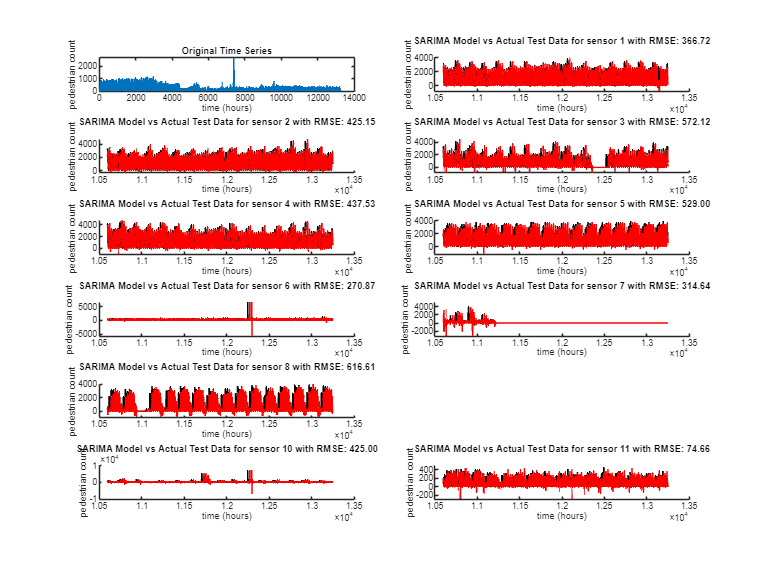


% Plot the original time series
figure;
subplot(round(length(UnqiueSensorNames)/2),2,1);
plot(timeseries, 'LineWidth', 1.5);
title('Original Time Series');
xlabel('time (hours)');
ylabel('pedestrian count');

for i = AppropriateRows
    %% Accuracy Comparison (RMSE)
    rmse_sarima = sqrt(mean((TestData(i,:)' - forecast_sarima(i,1:length(train_size+1:n))').^2));
    RMSEForTitle = sprintf(' with RMSE: %.2f\n', rmse_sarima);
    subplot(round(length(UnqiueSensorNames)/2),2,i+1); % Create a 4x1 grid of subplots and select the i-th one
    hold on
    plot(train_size+1:n, TestData(i,:), 'k', 'LineWidth', 1.5); hold on;
    plot(train_size+1:n, forecast_sarima(i,1:length(train_size+1:n)),'r', 'LineWidth', 1.5);
    plot(n:n+2, forecast_sarima(i,length(train_size+1:n):length(train_size+1:n)+2),'r', 'LineWidth', 1.5,'LineStyle',':');
    hold off
    title(['SARIMA Model vs Actual Test Data for sensor ' num2str(i) RMSEForTitle]);
    xlabel('time (hours)');
    ylabel('pedestrian count');
end


set(gcf,'units','inches','position',[0,0,16,12])

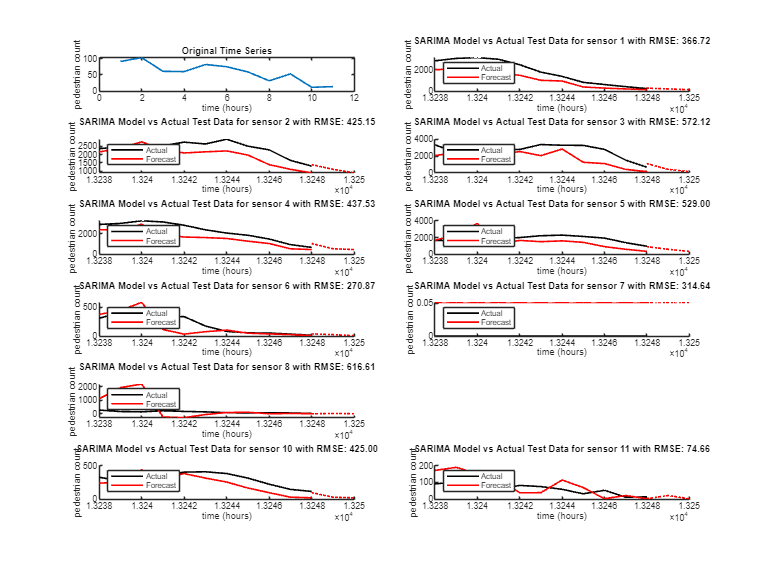


AmountOffEnd = 10;

% Plot the original time series
figure;
subplot(round(length(UnqiueSensorNames)/2),2,1);
plot(timeseries(end-AmountOffEnd:end), 'LineWidth', 1.5);
title('Original Time Series');
xlabel('time (hours)');
ylabel('pedestrian count');

for i = AppropriateRows
    %% Accuracy Comparison (RMSE)
    rmse_sarima = sqrt(mean((TestData(i,:)' - forecast_sarima(i,1:length(train_size+1:n))').^2));
    RMSEForTitle = sprintf(' with RMSE: %.2f\n', rmse_sarima);
    subplot(round(length(UnqiueSensorNames)/2),2,i+1); % Create a 4x1 grid of subplots and select the i-th one
    hold on
    plot(n-AmountOffEnd:n, TestData(i,end-AmountOffEnd:end), 'k', 'LineWidth', 1.5); hold on;
    plot(n-AmountOffEnd:n, forecast_sarima(i,end-AmountOffEnd:end),'r', 'LineWidth', 1.5);
    plot(n:n+2, forecast_sarima(i,length(train_size+1:n):length(train_size+1:n)+2),'r', 'LineWidth', 1.5,'LineStyle',':');
    hold off
    title(['SARIMA Model vs Actual Test Data for sensor ' num2str(i) RMSEForTitle]);
    xlabel('time (hours)');
    ylabel('pedestrian count');
    legend('Actual', 'Forecast',Location='northwest');
end


set(gcf,'units','inches','position',[0,0,16,12])

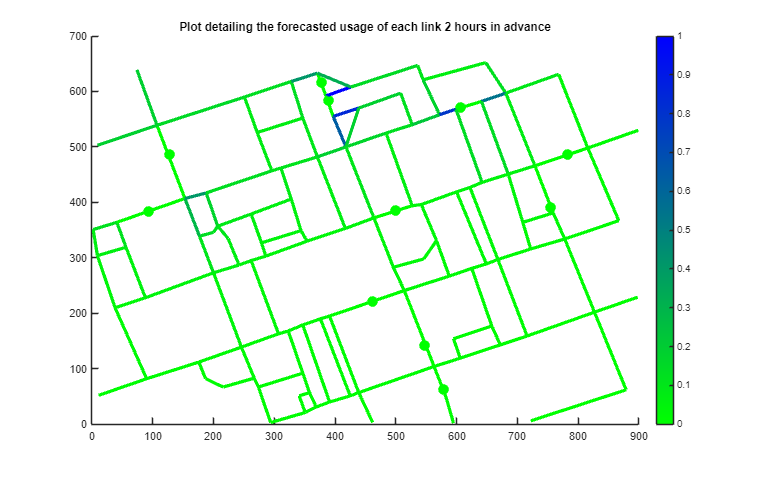

Traffic = zeros(length(alldists2(1,:)),1);
alldists2(alldists2 == 0) = NaN;
for i=1:length(Traffic)
    % All sensors
    for j=1:length(alldists2(:,1))
        Traffic(i) = Traffic(i) + forecast_sarima(j,end)*(1/(alldists2(j,i)^2));
    end
end

TrafficColourCodes = (Traffic - min(Traffic,[],'omitnan')) ./ (max(Traffic,[],'omitnan') - min(Traffic,[],'omitnan'));
TrafficColourCodes(isnan(TrafficColourCodes) | TrafficColourCodes == -inf) = 0;
TrafficColourCodes(TrafficColourCodes < 0) = -TrafficColourCodes(TrafficColourCodes < 0);
TrafficColourCodes = TrafficColourCodes./max(TrafficColourCodes);

figure;
RGB1 = [0, 1, 0];  % Red [R, G, B]
RGB2 = [0, 0, 1];  % Blue [R, G, B]

% Show sensor locations as green points
scatter(sensx, sensy, 100, 'g', 'filled'); % Size 100, color green, filled circles

% Loop through and plot each line segment
for i = 1:length(Traffic)
    RGB = (max(TrafficColourCodes) - TrafficColourCodes(i)) * RGB1 + TrafficColourCodes(i) * RGB2;

    % Plot line segment with specified color and width
    line([xs(2*i-1), xs(2*i)], [ys(2*i-1), ys(2*i)],'Color',RGB, 'LineWidth', 3);
end
% Apologies the colourbar to show the link flow usage was very difficult to
% plot
title('Plot detailing the forecasted usage of each link 2 hours in advance')
colormap([linspace(RGB1(1), RGB2(1), 255)', ...
                  linspace(RGB1(2), RGB2(2), 255)', ...
                  linspace(RGB1(3), RGB2(3), 255)']);  % Apply the custom colormap
colorbar;  % Display the colorbar

set(gcf,'units','inches','position',[0,0,16,10])

**(ii) Evaluate the performance of your model using data (note that marking places a higher emphasis on the quality of the evaluation than on the prediction accuracy).**

Evaluating performance of the model:

- When training the SARIMA model it tests poorly on most sensors when compared to when tested in the lab. It produces RMSE scores of up to 616 on sensor 8 with a low score of 270 on sensor 6. This is higher than the RMSE score of 220 obtained in the lab sheet although not by much and is heavily dependent on the sensor selected. This highlights however that a larger sample size doesn't necessarily correlate with more accuracte scores for the SARIMA model and that the quality of data is much more important.

- Something else that can be noticed is the discontinuity in the forecasts for the network that can be compared to real data and the forecasts for 2 hours in advance. This is a criticism of the approach and not necessarily the data as discontinuities normally arise from how the training and testing data is split although the poor quality of data also has an impact here.

- In short, the model performs poorly with the colour coded links above only showing high traffic forecasted on small roads. This is caused by the gravity model approach where the longer the street, the less close it is to be to a sensor as the midpoint is taken of the link. This therefore means shorter roads very close to sensors, like the ones seen at the top, will always predict higher pedestrian traffic on this part of the network while the other longer links predict much much lower pedestrian traffic than in reality.